# Eigenvalue equation solver: calculate n_eff for specific core radius

## Input

clear; clc;

% Parameters
lambda = 1.55e-6;              % Wavelength (m)
n_co   = 1.4508;               % Core refractive index
n_cl   = 1.4440;               % Cladding refractive index
k0     = 2*pi/lambda;          % Free-space wavenumber
a0     = 125/15.24/2;          % Target core radius (micron)  

% Mode indices (HE_11)
nu = 1; % azimuthal order

% Core radius sweep
a_vec = linspace(0, 8e-6, 200); 
beta_sol = NaN(size(a_vec));


## Solve equation

for ii = 1:length(a_vec)
    a = a_vec(ii);
    
    % Define mode equation
    fun = @(beta) mode_eq(beta, a, k0, n_co, n_cl, nu, lambda);
    
    % Valid beta range
    beta_min = k0*n_cl*1.001;
    beta_max = k0*n_co*0.999;
    
    % Solve only for fundamental root (HE11)
    try
        beta_sol(ii) = fzero(fun, [beta_min beta_max]);
    catch
        beta_sol(ii) = NaN; % no solution for this radius
    end
end

% Calculate intersect
x_intersect = a0;  
y_intersect = interp1(a_vec*1e6, beta_sol/k0, x_intersect, 'linear');


## Plot

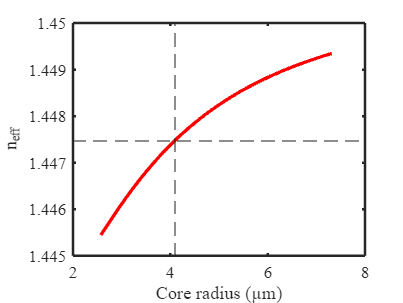

% Plot effective index
figure; hold on; box on;
plot(a_vec*1e6, beta_sol/k0, 'r', 'LineWidth', 1.5);
xline(x_intersect, '--');
yline(y_intersect, '--');
xlabel('Core radius (µm)');
ylabel('n_{eff}');
set(gca, 'FontName', 'mlmodern', 'FontSize', 10, 'LineWidth', 1.5);


% Display intersection point
disp(['n_{eff} = ', num2str(y_intersect)]);

n_{eff} = 1.4475


## Equation function

function F = mode_eq(beta, a, k0, n_co, n_cl, nu, lambda)
    U = a*sqrt(k0^2*n_co^2 - beta.^2);
    W = a*sqrt(beta.^2 - k0^2*n_cl^2);
    V = 2*pi * a/lambda * sqrt(n_co^2 - n_cl^2);    % Fiber parameter 

    % Bessel and modified Bessel functions
    Jv   = besselj(nu, U);
    Jvp  = besselj(nu-1, U) - nu./U .* Jv;
    Kv   = besselk(nu, W);
    Kvp  = -besselk(nu-1, W) - nu./W .* Kv;

    term1 = Jvp./(U.*Jv) + Kvp./(W.*Kv);
    term2 = Jvp./(U.*Jv) + (n_cl^2/n_co^2) * (Kvp./(W.*Kv));
    
    lhs = term1 .* term2;
    rhs = (nu*beta/(k0*n_co)).^2 .* (V./(U.*W)).^4;

    F = lhs - rhs;
end


## Save

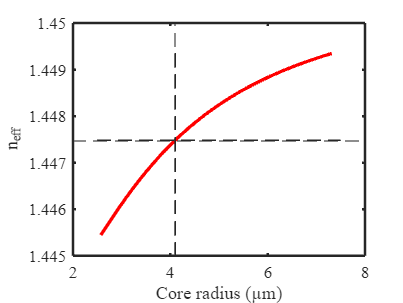

matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\DATA_n_eff_standard.tex',...
    'relativeDataPath', 'Figures','showInfo', false,...
    'extraAxisOptions', {'width=\linewidth'});